การคำนวณหาค่า H ที่สถานี S3 (M7) จากค่า Q ระหว่าง Day 1 และ Day 60 

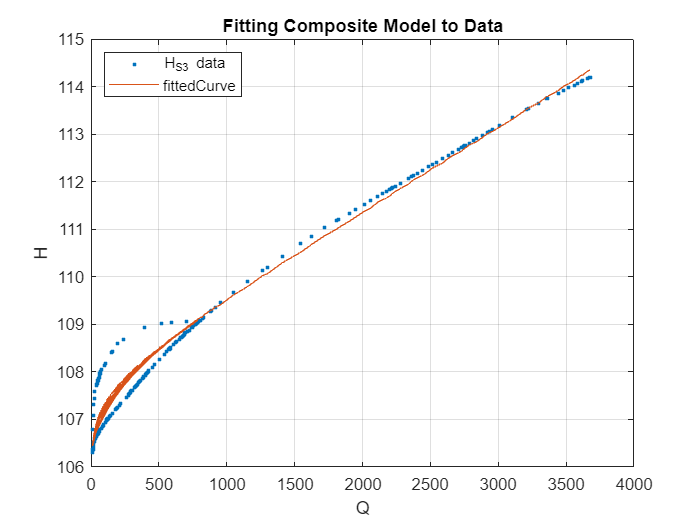

mdl = fittype('a*cos(x+f) + b*x^2 +c*x + d*log(x) + e','coefficients',{'a','b','c','d','e','f'},'independent','x','dependent','y');
fitResult = fit(QS3,HS3,mdl,'StartPoint',[0,0,0,0,0,1]);
coeffs = coeffvalues(fitResult);
a = coeffs(1);
b = coeffs(2);
c = coeffs(3);
d = coeffs(4);
e = coeffs(5);
f = coeffs(6);
nv = a * cos(QS3+f) + b * QS3.^2 + c*QS3 +d * log(QS3) + e;

plot(QS3,HS3,'.')
hold on
plot(QS3,nv)
hold off
grid on
xlabel('Q');
ylabel('H');
title('Fitting Composite Model to Data');
legend({'H_S3 data','fittedCurve'},'Location','northwest');

Performance ของการ Fitting

R_squared = 1 - sum((HS3 - nv).^2) / sum((HS3 - mean(HS3)).^2);
MAE = sum(abs(HS3 - nv))/length(HS3);
MSE = (sum((HS3 - nv).^2))/(length(HS3));
fprintf('R_squared = %f\nMAE = %f\nMSE = %f', R_squared,MAE,MSE);

R_squared = 0.968918
MAE = 0.302317
MSE = 0.153341

Predict และแสดงค่า H ของสถานี S3

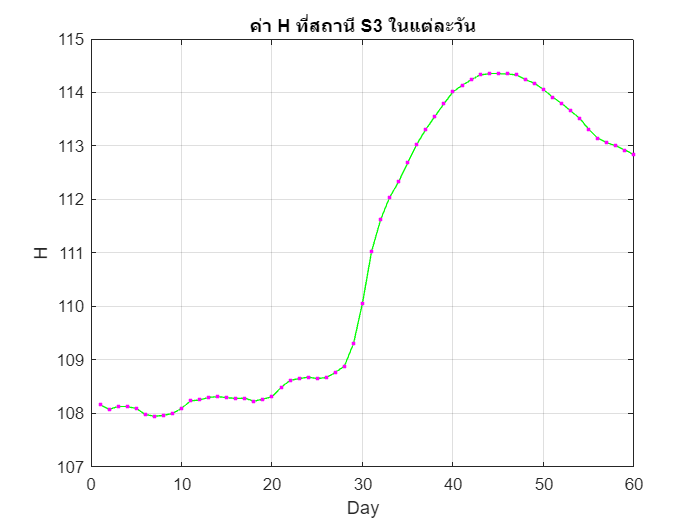

H3 = a * cos(Q3+f) + b * Q3.^2 + c*Q3 +d * log(Q3) + e;
plot(1:60,H3,'g')
hold on
plot(1:60,H3,'m.')
hold off
grid on
xlabel('Day');
ylabel('H');
title('ค่า H ที่สถานี S3 ในแต่ละวัน');